
ADHD = {v10p v12p v14p v15p v173 v18p v19p v1p v20p v21p v22p v24p v25p v27p v28p v29p v30p v31p v32p v33p v34p v35p v36p v37p v38p v39p v3p v40p v6p v8p
};
  
Control = {v107 v108 v109 v110 v111 v112 v113 v114 v115 v116 v41p v42p v43p v44p v45p v46p v47p v48p v49p v50p v51p v52p v53p v54p v55p v56p v57p v58p v59p v60p};

ADHD = ADHD(:);
entropy_ADHD = zeros(size(ADHD));

for i=1:size(entropy_ADHD,1)
    [~, eLag , eDim]= phaseSpaceReconstruction(ADHD{i}); 
    entropy_ADHD(i) = approximateEntropy(ADHD{i},eLag, eDim);
    display(num2str(i)+" done")
end

    entropy_ADHD    

Control = Control(:);
entropy_Control = zeros(size(Control));

for i=1:size(entropy_Control,1)
    [~, eLag , eDim]= phaseSpaceReconstruction(Control{i});   
    entropy_Control(i) = approximateEntropy(Control{i}, eLag, eDim);
    display(num2str(i)+" done")
end

entropy_Control

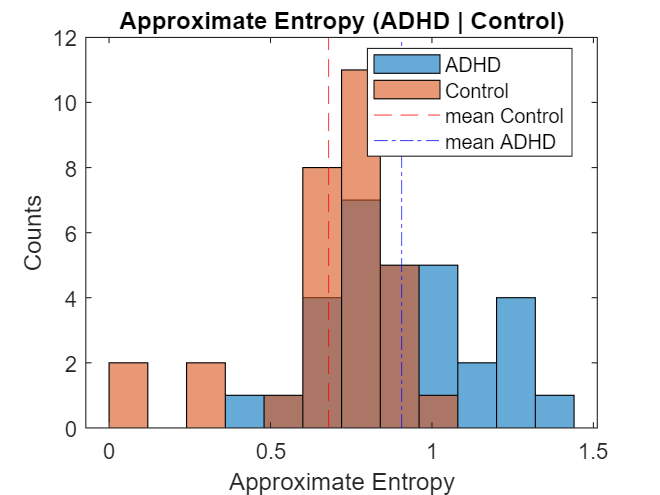

histogram(entropy_ADHD, 'BinWidth',0.12)
hold on
histogram(entropy_Control, 'BinWidth',0.12)

xline(mean(entropy_Control), 'r--')
xline(mean(entropy_ADHD),'b-.')

legend(["ADHD", "Control", "mean Control", "mean ADHD"], "Location","best")
title("Approximate Entropy (ADHD | Control)")
xlabel("Approximate Entropy")
ylabel("Counts")
hold off

ADHD = ADHD(:);
corr_ADHD = zeros(size(ADHD));

for i=1:size(entropy_ADHD,1)
    [~, eLag , eDim]= phaseSpaceReconstruction(ADHD{i}); 
    corr_ADHD(i) = correlationDimension(ADHD{i},eLag, eDim);
    display(num2str(i)+" done")
end  

Control = Control(:);
corr_Control = zeros(size(Control));

for i=1:size(entropy_Control,1)
    [~, eLag , eDim]= phaseSpaceReconstruction(Control{i});   
    corr_Control(i) = correlationDimension(Control{i}, eLag, eDim);
    display(num2str(i)+" done")
end

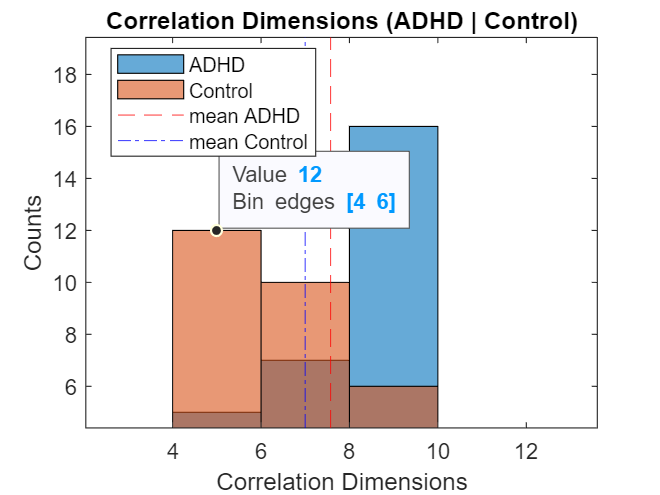

histogram(corr_ADHD)
hold on
histogram(corr_Control)

xline(mean(corr_ADHD), 'r--')
xline(mean(corr_Control),'b-.')

legend(["ADHD", "Control", "mean ADHD", "mean Control"], "Location","best")
title("Correlation Dimensions (ADHD | Control)")
xlabel("Correlation Dimensions")
ylabel("Counts")
hold off

CPly_mean = mean(CPly,2)

CPly_mean =    14.9011
   22.2830
   13.1108
   13.6918
   11.6540
   11.2601
   23.2024
   17.2212
   23.5597
   17.4137


CPly_mean_ADHD = mean(CPly1,2)

CPly_mean_ADHD =    22.1933
   25.4365
    3.6254
   22.4121
   22.2214
   11.0995
   21.2009
   23.8583
   22.3188
   30.9875


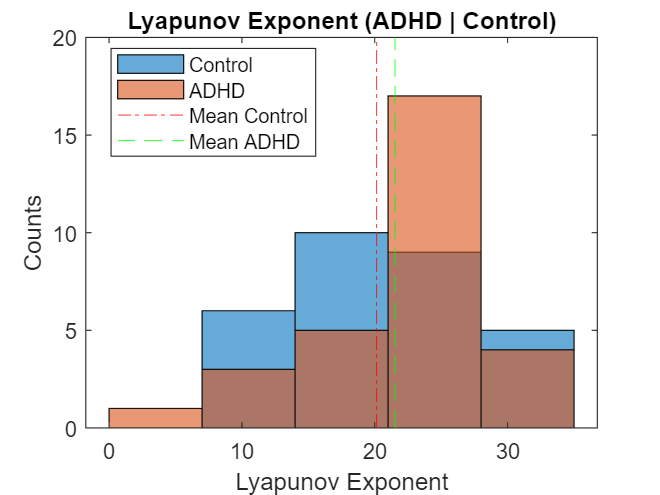

histogram(CPly_mean, BinWidth=7)
hold on
histogram(CPly_mean_ADHD, BinWidth=7)
xline(mean(CPly_mean),'r-.')
xline(mean(CPly_mean_ADHD),'g--')

legend(["Control", "ADHD", "Mean Control", "Mean ADHD"], Location="best")
xlabel("Lyapunov Exponent")
ylabel("Counts")
title("Lyapunov Exponent (ADHD | Control)")

hold off

ADHD_data = [corr_ADHD entropy_ADHD CPly_mean_ADHD zeros(size(CPly_mean_ADHD))];
Control_Data = [corr_Control entropy_Control CPly_mean ones(size(CPly_mean))];

Data = [ADHD_data;Control_Data];

Params = Data(:,[1 3]);
Label = Data(:,4);

pleasing = [mean(cd21,1)' mean(ly21,1)' zeros(30,1)];
non_pleasing = [mean(cd25,1)' mean(ly25,1)' ones(30,1)];

music = [pleasing; non_pleasing];

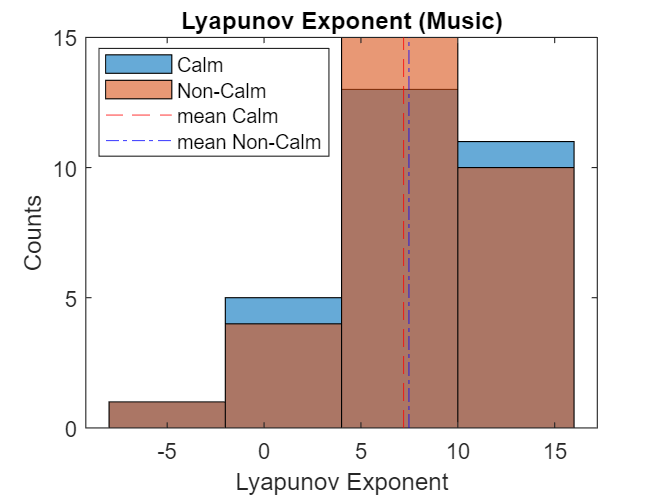

histogram(mean(ly21,1)',NumBins=4)
hold on
histogram(mean(ly25,1)',NumBins=4)

xline(mean(mean(ly21,1)), 'r--')
xline(mean(mean(ly25,1)),'b-.')

legend(["Calm", "Non-Calm", "mean Calm", "mean Non-Calm"], "Location","best")
title("Lyapunov Exponent (Music)")
xlabel("Lyapunov Exponent")
ylabel("Counts")
hold off
hold off

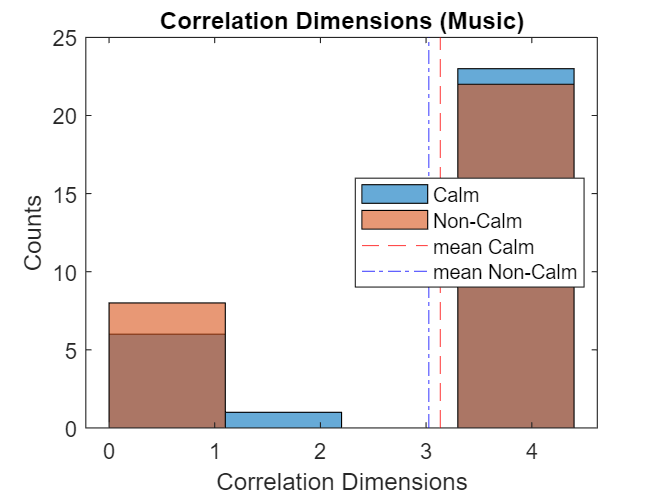

histogram(mean(cd21,1)',NumBins=4)
hold on
histogram(mean(cd25,1)',NumBins=4)

xline(mean(mean(cd21,1)), 'r--')
xline(mean(mean(cd25,1)),'b-.')

legend(["Calm", "Non-Calm", "mean Calm", "mean Non-Calm"], "Location","best")
title("Correlation Dimensions (Music)")
xlabel("Correlation Dimensions")
ylabel("Counts")
hold off
hold off

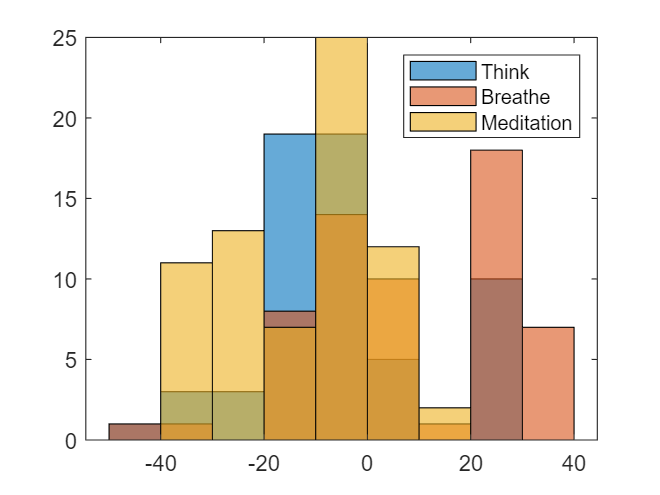

think_ly = HT1_think_ly;
breathe_ly = HT1_breathe_ly;
medit_ly = HT1_medit_ly;

histogram(think_ly, BinWidth=10)
hold on
histogram(breathe_ly, BinWidth=10)
histogram(medit_ly, BinWidth=10)

legend(["Think", "Breathe", "Meditation"])
hold off

think_ly = SNY3_think_ly;
breathe_ly = SNY3_breathe_ly;
medit_ly = SNY3_medit_ly;

histogram(think_ly, BinWidth=10)
hold on
histogram(breathe_ly, BinWidth=10)
histogram(medit_ly, BinWidth=10)

legend(["Think", "Breathe", "Meditation"])
hold off

think_cd = CTR_think_cd;
breathe_cd = CTR_breathe_cd;


histogram(think_cd)
hold on
histogram(breathe_cd)


legend(["Think", "Breathe"])
hold off

think_cd = VIP1_think_cd;
breathe_cd = VIP1_breathe_cd;
medit_cd = VIP1_medit_cd;

histogram(think_cd)
hold on
histogram(breathe_cd)
histogram(medit_cd)

legend(["Think", "Breathe", "Meditation"])
hold off

think_cd = HT1_think_cd;
breathe_cd = HT1_breathe_cd;
medit_cd = HT1_medit_cd;

histogram(think_cd)
hold on
histogram(breathe_cd)
histogram(medit_cd)

legend(["Think", "Breathe", "Meditation"])
hold off

think_cd = SNY3_think_cd;
breathe_cd = SNY3_breathe_cd;
medit_cd = SNY3_medit_cd;

histogram(think_cd)
hold on
histogram(breathe_cd)
histogram(medit_cd)

legend(["Think", "Breathe", "Meditation"])
hold off

histogram(mean(HT1_breathe_ly))
hold on
histogram(mean(CTR_breathe_ly))
histogram(mean(VIP1_breathe_ly))
histogram(mean(SNY3_breathe_ly))

legend(["Himalayan", "Control", "Vipassanā", "Isha shoonya"], Location='best')
hold off

ly_breathe = [mean(CTR_breathe_ly), mean(HT1_breathe_ly), mean(SNY3_breathe_ly) , mean(VIP1_breathe_ly) ]

ly_breathe =    20.2853    7.8156   17.6106    9.5079


ly_think = [mean(CTR_think_ly), mean(HT1_think_ly), mean(SNY3_think_ly) , mean(VIP1_think_ly) ]

ly_think =    20.7663   -5.1251   23.5451   -8.2707


ly_medit = [mean(CTR_think_ly), mean(HT1_medit_ly), mean(SNY3_medit_ly) , mean(VIP1_medit_ly) ]

ly_medit =    20.7663  -11.9546   18.1227    6.9422


Subjects = categorical(["Control", "Himalayan", "Isha Shoonya", "Vipassanā"])

Subjects = 1×4 categorical array
     Control      Himalayan      Isha Shoonya      Vipassanā 


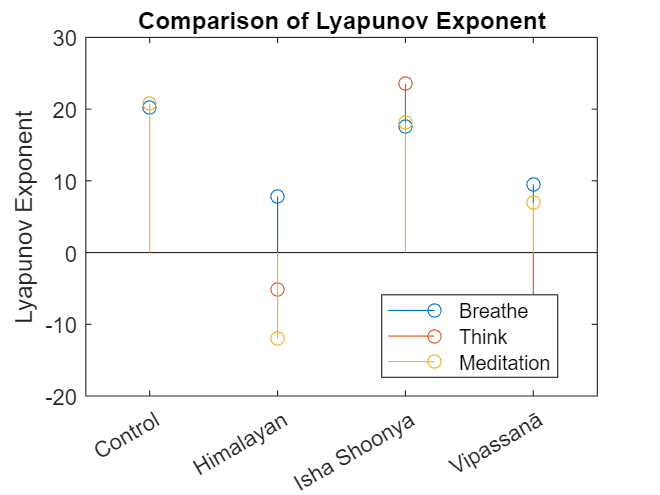


stem(Subjects,ly_breathe)
hold on
stem(Subjects,ly_think)
stem(Subjects,ly_medit)

legend(["Breathe", "Think", "Meditation"], Location="best")
ylabel("Lyapunov Exponent")
title('Comparison of Lyapunov Exponent')
hold off

ly_breathe = [mean(CTR_breathe_cd), mean(HT1_breathe_cd), mean(SNY3_breathe_cd) , mean(VIP1_breathe_cd) ]

ly_breathe =     3.9752    3.9600    0.4655    4.0000


ly_think = [mean(CTR_think_cd), mean(HT1_think_cd), mean(SNY3_think_cd) , mean(VIP1_think_cd) ]

ly_think =     0.4758    0.5123    0.4938    3.9601


ly_medit = [mean(CTR_think_cd), mean(HT1_medit_cd), mean(SNY3_medit_cd) , mean(VIP1_medit_cd) ]

ly_medit =     0.4758    0.4823    3.9703    0.4666


Subjects = categorical(["Control", "Himalayan", "Isha Shoonya", "Vipassanā"])

Subjects = 1×4 categorical array
     Control      Himalayan      Isha Shoonya      Vipassanā 


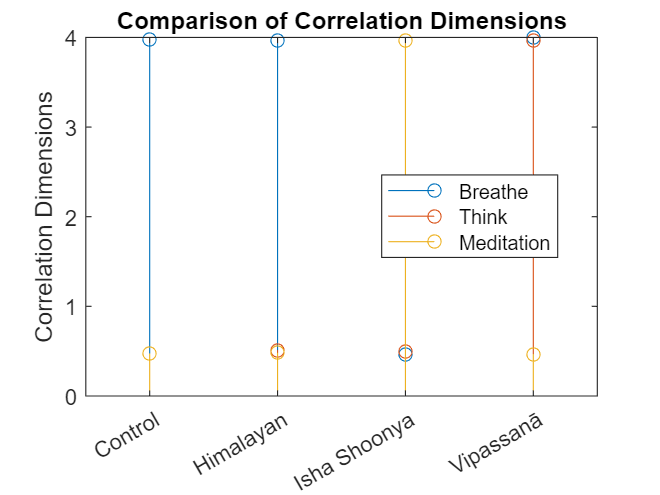


stem(Subjects,ly_breathe)
hold on
stem(Subjects,ly_think)
stem(Subjects,ly_medit)

legend(["Breathe", "Think", "Meditation"], Location="best")
ylabel("Correlation Dimensions")
title('Comparison of Correlation Dimensions')
hold off